Ex 5

syms r1 r2 r3 r4 thetadotm real

thetadotm = 10;
r1 = 20; r2 = 60; r3 = 8; r4 = 32;

nrm = r2/r1

nrm = 3

nrg = r4/r3

nrg = 4

thetadotg = -thetadotm/nrm

thetadotg = -3.3333

thetadotl = thetadotg/nrg

thetadotl = -0.8333

nr = abs(thetadotm/thetadotl)

nr = 12

T = (pi/2)/abs(thetadotl)

T = 1.8850

Ex 4

syms S D L t tau T q q0 q1 q2 v1 real;
N = 3; %number of knots

L = 1; S = 0; D = 3;

q0 = [S; pi/2]

q0 =          0
    1.5708


q1 = [S+D/2-0.96*L; 1/4]

q1 =     0.5400
    0.2500


q2 = [S+D; pi/2]

q2 =     3.0000
    1.5708


syms a0; a = sym("a%d",[1,3])

$$a = \left(\begin{array}{ccc} a_{1} & a_{2} & a_{3} \end{array}\right)$$

syms b0; a = sym("b%d",[1,3])

$$a = \left(\begin{array}{ccc} b_{1} & b_{2} & b_{3} \end{array}\right)$$

a0 = q0;
a1 = 0;
a2 = 3*(q1-q0) - T/2*v1;
a3 = -2*(q1-q0) + T/2*v1;

theta0 = vpa(subs(simplify(a0 + a1*tau + a2*tau^2 + a3*tau^3),T,4))

$$theta0 = \left(\begin{array}{c} -37.08\,\tau^{3}-34.38\,\tau^{2}\\ 2.6415926535897931159979634685442\,\tau^{3}-3.9623889803846896739969452028163\,\tau^{2}+1.5707963267948966192313216916398 \end{array}\right)$$

b0 = q1;
b1 = 0;
b2 = 3*(q2 - q1) - T*v1;
b3 = -2*(q2 - q1) - (3/4)*T^2*(q2-q0);
theta1 = vpa(subs(simplify(b0 + b1*tau + b2*tau^2 + b3*tau^3),T,4))

$$theta1 = \left(\begin{array}{c} -40.92\,\tau^{3}-28.62\,\tau^{2}+0.54\\ -2.6415926535897931159979634685442\,\tau^{3}+3.9623889803846896739969452028163\,\tau^{2}+0.25 \end{array}\right)$$

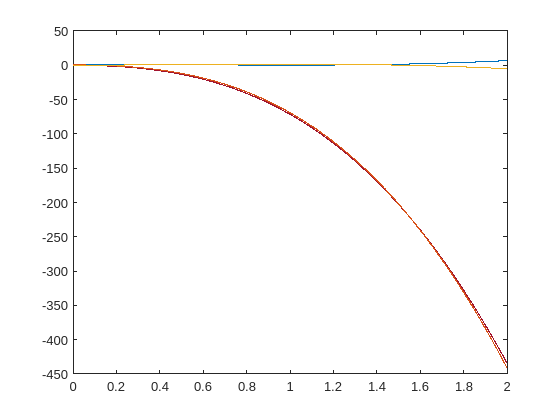

theta0 = subs(theta0,tau,0:0.001:2);
theta1 = subs(theta1,tau,0:0.001:2);
tau = 0:0.001:2;
plot(tau,theta0); hold on;
plot(tau,theta1); hold on;

Ex 3

syms L q1 q2 q3 real
DH = [0 L 0 q1; 0 L 0 q2; 0 L 0 q3];
[T,A] = directkin(DH);
fr = T(1:3,4);
Jl = jacobian(fr,[q1,q2,q3]);
Ja = [0 0 0; 0 0 0; 1 1 1];
J = [Jl ; Ja]

$$J = \begin{array}{l} \left(\begin{array}{ccc} -L\,\left(\sigma_{1}+\sin\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right)\right) & -L\,\left(\sigma_{1}+\sin\left(q_{1}+q_{2}\right)\right) & -L\,\sigma_{1}\\ L\,\left(\sigma_{2}+\cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right)\right) & L\,\left(\sigma_{2}+\cos\left(q_{1}+q_{2}\right)\right) & L\,\sigma_{2}\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 1 & 1 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(q_{1}+q_{2}+q_{3}\right)\\ \sigma_{2}=\cos\left(q_{1}+q_{2}+q_{3}\right) \end{array}$$

Jr = [Jl(1:2,:) ; 1 1 1]

$$Jr = \begin{array}{l} \left(\begin{array}{ccc} -L\,\left(\sigma_{1}+\sin\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right)\right) & -L\,\left(\sigma_{1}+\sin\left(q_{1}+q_{2}\right)\right) & -L\,\sigma_{1}\\ L\,\left(\sigma_{2}+\cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right)\right) & L\,\left(\sigma_{2}+\cos\left(q_{1}+q_{2}\right)\right) & L\,\sigma_{2}\\ 1 & 1 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(q_{1}+q_{2}+q_{3}\right)\\ \sigma_{2}=\cos\left(q_{1}+q_{2}+q_{3}\right) \end{array}$$

simplify(det(A{1}(1:3,1:3)' * Jr))

$$ans = L^{2}\,\sin\left(q_{2}\right)$$

simplify(inv(Jr))

$$ans = \left(\begin{array}{ccc} \frac{\cos\left(q_{1}+q_{2}\right)}{L\,\sin\left(q_{2}\right)} & \frac{\sin\left(q_{1}+q_{2}\right)}{L\,\sin\left(q_{2}\right)} & \frac{\sin\left(q_{3}\right)}{\sin\left(q_{2}\right)}\\ -\frac{\cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right)}{L\,\sin\left(q_{2}\right)} & -\frac{\sin\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right)}{L\,\sin\left(q_{2}\right)} & -\frac{\sin\left(q_{2}+q_{3}\right)+\sin\left(q_{3}\right)}{\sin\left(q_{2}\right)}\\ \frac{\cos\left(q_{1}\right)}{L\,\sin\left(q_{2}\right)} & \frac{\sin\left(q_{1}\right)}{L\,\sin\left(q_{2}\right)} & \frac{\sin\left(q_{2}+q_{3}\right)+\sin\left(q_{2}\right)}{\sin\left(q_{2}\right)} \end{array}\right)$$

Ex 2

Ri = euler_dir("yxy",[pi/4,-pi/4,pi - pi/3])

Ri =    -0.7866   -0.5000    0.3624
   -0.6124    0.7071   -0.3536
   -0.0795   -0.5000   -0.8624


phi = pi/3;
Rf = [0 sin(phi) cos(phi); 0 cos(phi) -sin(phi); -1 0 0]

Rf =          0    0.8660    0.5000
         0    0.5000   -0.8660
   -1.0000         0         0


R = Ri' * Rf

R =     0.0795   -0.9874    0.1370
    0.5000   -0.0795   -0.8624
    0.8624    0.1370    0.4874


[r,theta] = axisangle_inv(R)

regular solution


r =     0.5170   -0.3752    0.7694
   -0.5170    0.3752   -0.7694


theta =     1.8300   -1.8300
